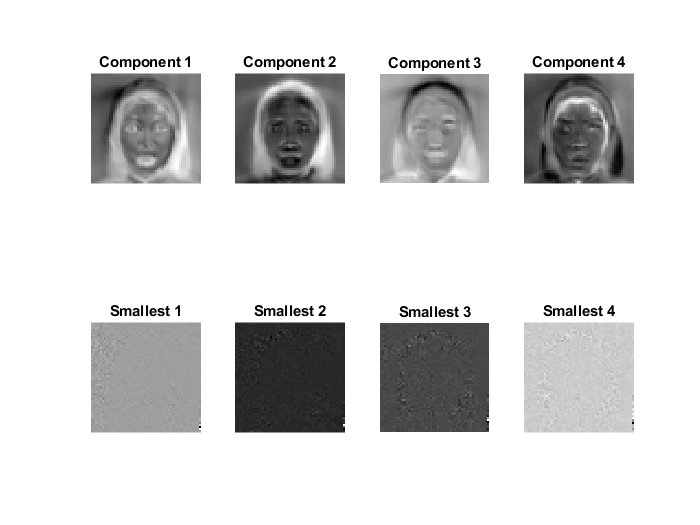

clc; clear; close all;

image_files = dir('*.tiff'); 
num_images = length(image_files);
if num_images == 0
    error('هیچ تصویری یافت نشد.');
end

img = imread(image_files(1).name);
img=imresize(img,[50,50]);
[h, w] = size(img); 
d = h * w; 
X = zeros(d, num_images);

for i = 1:num_images
    img = imread(image_files(i).name);
    img=imresize(img,[50,50]);
    X(:, i) = double(img(:)); 
end

X_mean = mean(X, 2);
X_centered = X - X_mean;
C = cov(X_centered');

[eigenvectors, eigenvalues_matrix] = eig(C);
eigenvalues = diag(eigenvalues_matrix);

[eigenvalues_sorted, idx] = sort(eigenvalues, 'descend');
eigenvectors_sorted = eigenvectors(:, idx);

figure;
for i = 1:4
    subplot(2, 4, i);
    imshow(reshape(eigenvectors_sorted(:, i), [h, w]), []);
    title(['Component ' num2str(i)]);
    
    subplot(2, 4, i+4);
    imshow(reshape(eigenvectors_sorted(:, end-i+1), [h, w]), []);
    title(['Smallest ' num2str(i)]);
end

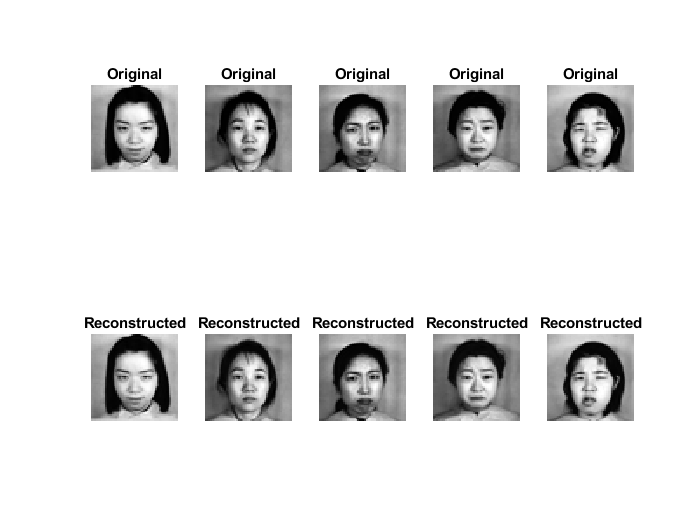


k = 150;
V = eigenvectors_sorted(:, 1:k); 

num_test_images = 5; 
test_indices = randperm(num_images, num_test_images); 
reconstructed_images = zeros(d, num_test_images);

for j = 1:num_test_images
    original = X_centered(:, test_indices(j)); 
    projection = V' * original; 
    reconstructed = V * projection + X_mean; 
    reconstructed_images(:, j) = reconstructed;
end

figure;
for j = 1:num_test_images
    subplot(2, num_test_images, j);
    imshow(reshape(X(:, test_indices(j)), [h, w]), []);
    title('Original');

    subplot(2, num_test_images, j + num_test_images);
    imshow(reshape(reconstructed_images(:, j), [h, w]), []);
    title('Reconstructed');
end